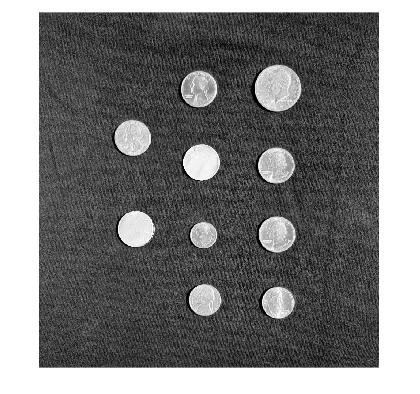

% testImageIdx = randi([1,3]);
testImageIdx = 3;
testCoinImage = imread("..\..\Data\Data\MathWorks Images\testCoinImage" + testImageIdx + ".png");
figure, imshow(testCoinImage)

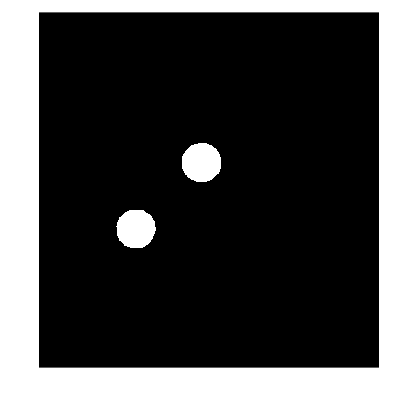


[testCoinMask, maskedTestCoinImage] = segmentCoinImage(testCoinImage);

maskedTestCoinImageGs = imgaussfilt(maskedTestCoinImage, ...
    2.47);
edges = edge(im2gray(maskedTestCoinImageGs),"log");

mask2 = xor(edges,testCoinMask);
maskBlankCoin = filterBlankCoins(mask2);
imshow(maskBlankCoin)

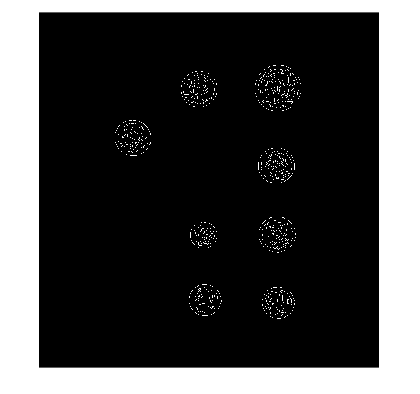

faceEdgeMask = edges & ~maskBlankCoin;
imshow(faceEdgeMask)

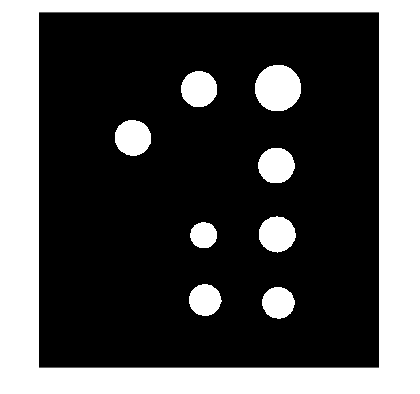

validCoinMask = testCoinMask & expandEdgeRegions(maskedTestCoinImage,faceEdgeMask);
imshow(validCoinMask)


coin50Mask = bwpropfilt(validCoinMask,"Perimeter",[380,400]);
% imshow(coin50mask)
coinQuarterMask = bwpropfilt(validCoinMask,"Perimeter",[300,320]);
% imshow(coinQuarterMask)
coinNickelMask = bwpropfilt(validCoinMask,"Perimeter",[260,280]);
% imshow(coinNickelMask)
coinDimeMask = bwpropfilt(validCoinMask,"Perimeter",[210,250]);
% imshow(coinDimeMask)
nFiftyCents = size(regionprops("table",coin50Mask,"all"),1);

nFiftyCents = 1

nQuarters = size(regionprops("table",coinQuarterMask,"all"),1);
nNickels = size(regionprops("table",coinNickelMask,"all"),1);
nDimes  = size(regionprops("table",coinDimeMask,"all"),1);
USD = nFiftyCents*0.5 + nQuarters*0.25 + nNickels*0.05 + nDimes*0.1;


function [BW,maskedImage] = segmentCoinImage(X)
%segmentImage イメージの領域分割アプリから自動生成されたコードを使用してイメージをセグメント化
%  [BW,MASKEDIMAGE] = segmentImage(X) イメージの領域分割アプリから自動生成されたコードを使用してイメージ X
%  をセグメント化します。最終セグメンテーションは BW で返され、マスク イメージは MASKEDIMAGE で返されます。

% Auto-generated by imageSegmenter app on 18-Feb-2023
%----------------------------------------------------

X = im2gray(X);

% 空のマスクを作成
BW = false(size(X,1),size(X,2));

% イメージのしきい値処理 - グローバルしきい値
BW = imbinarize(im2gray(X));

% default によるマスクのオープン
radius = 2;
decomposition = 0;
se = strel('disk', radius, decomposition);
BW = imopen(BW, se);

% 穴の塗りつぶし
BW = imfill(BW, 'holes');

% Create masked image.
maskedImage = X;
maskedImage(~BW) = 0;
end

function [BW_out,properties] = filterRegions(BW_in)
%filterRegions Filter BW image using auto-generated code from imageRegionAnalyzer app.

% Auto-generated by imageRegionAnalyzer app on 18-Feb-2023
%---------------------------------------------------------

BW_out = BW_in;

% Filter image based on image properties.
BW_out = bwpropfilt(BW_out,'Area',[1000 + eps(1000), Inf]);
BW_out = bwpropfilt(BW_out,'EulerNumber',[-Inf, -50 - eps(-50)]);

% Get properties.
properties = regionprops(BW_out, {'Area', 'Eccentricity', 'EquivDiameter', 'EulerNumber', 'MajorAxisLength', 'MinorAxisLength', 'Orientation', 'Perimeter'});
end

function [BW,maskedImage] = erodeCoinMask(X,MASK)
%segmentImage イメージの領域分割アプリから自動生成されたコードを使用してイメージをセグメント化
%  [BW,MASKEDIMAGE] = segmentImage(X,MASK) イメージの領域分割アプリから自動生成されたコードを使用してイメージ
%  X をセグメント化します。最終セグメンテーションは BW で返され、マスク イメージは MASKEDIMAGE で返されます。

% Auto-generated by imageSegmenter app on 18-Feb-2023
%----------------------------------------------------


% 空のマスクを作成
BW = false(size(X,1),size(X,2));

% Load Mask
BW = MASK;

% disk によるマスクの収縮
radius = 10;
decomposition = 0;
se = strel('disk', radius, decomposition);
BW = imerode(BW, se);

% Create masked image.
maskedImage = X;
maskedImage(~BW) = 0;
end

function [BW_out,properties] = filterBlankCoins(BW_in)
%filterRegions Filter BW image using auto-generated code from imageRegionAnalyzer app.

% Auto-generated by imageRegionAnalyzer app on 18-Feb-2023
%---------------------------------------------------------

BW_out = BW_in;

% Filter image based on image properties.
BW_out = bwpropfilt(BW_out,'Area',[11 + eps(11), Inf]);
BW_out = bwpropfilt(BW_out,'EulerNumber',[-120 + eps(-120), Inf]);
BW_out = imfill(BW_out,"holes");

% default によるマスクの膨張
radius = 5;
decomposition = 0;
se = strel('disk', radius, decomposition);
BW_out = imdilate(BW_out, se);

% Get properties.
properties = regionprops(BW_out, {'Area', 'Eccentricity', 'EquivDiameter', 'EulerNumber', 'MajorAxisLength', 'MinorAxisLength', 'Orientation', 'Perimeter'});
end

function [BW,maskedImage] = expandEdgeRegions(X,MASK)
%segmentImage イメージの領域分割アプリから自動生成されたコードを使用してイメージをセグメント化
%  [BW,MASKEDIMAGE] = segmentImage(X,MASK) イメージの領域分割アプリから自動生成されたコードを使用してイメージ
%  X をセグメント化します。最終セグメンテーションは BW で返され、マスク イメージは MASKEDIMAGE で返されます。

% Auto-generated by imageSegmenter app on 18-Feb-2023
%----------------------------------------------------


% 空のマスクを作成
BW = false(size(X,1),size(X,2));

% Load Mask
BW = MASK;

% default によるマスクの膨張
radius = 7;
decomposition = 0;
se = strel('disk', radius, decomposition);
BW = imdilate(BW, se);

% default によるマスクの膨張
radius = 9;
decomposition = 0;
se = strel('disk', radius, decomposition);
BW = imdilate(BW, se);

% Create masked image.
maskedImage = X;
maskedImage(~BW) = 0;
end
